# Design of a Controller with Requirements on the Performance against Disturbances 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

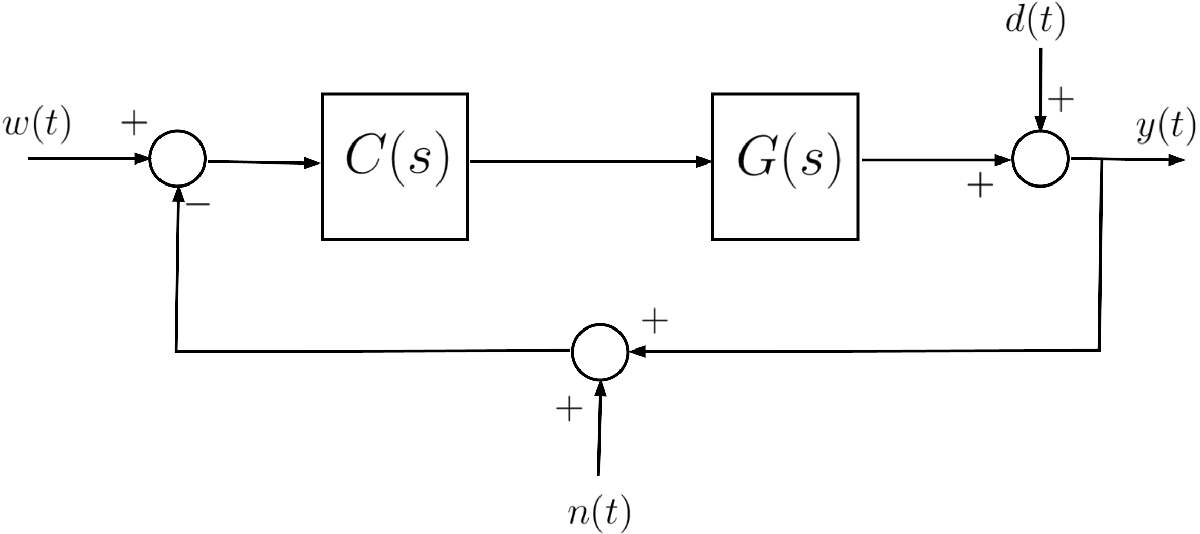	

where $G(s)$ is given by                


$$G(s) = 2\frac{(1+10s)}{(1+s)^2}$$


## **Questions**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $|e(\infty)|=0$ for $w(t) = \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function;

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[0.1\,,\; 0.5\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $w(t)=0$, $n(t)=0$, $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/5$;

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \in \left[20,\,200\right]\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/10$.	

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

The system described by the transfer function $G(s)$ is minimum-phase. Hence we proceed by a standard loop-shaping design of the controller $C(s)$through the following logical steps:

#### Requirements Analysis

**Requirement (Q1.2)**: The transfer function $T_{d,\,y}(s)$ from the input $d(t)$ to the output $y(t)$ is the sensitivity function $S(s)$ [refer to Part 9 of the course material, slides 34--36, 45--48]:


$$T_{d,\,y}(s) = S(s) = \frac{1}{1+L(s)}$$


Consider the frequency response associated with $T_{d,\,y}(s)$ and let's use the approximation introduced in Part 9 - Slide 48 of the course material:


$$\left\vert T_{d,\,y}(j \omega) \right\vert = \left\vert S(j \omega)\right\vert = \frac{1}{\left\vert 1+L(j\omega)\right\vert} \approx 
\left\{
\begin{array}{ll}
\frac{1}{\left\vert L(j\omega)\right\vert}\, , & \text{when } \left\vert L(j \omega) \right\vert \gg 1\\
1\, , &  \text{when } \left\vert L(j \omega) \right\vert \ll 1
\end{array} 
\right.$$


According to Req. (Q1.2)


$$d(t) = D \sin \left(\bar{\omega}\,t\right) \cdot 1(t)\,,\quad \bar{\omega} \in \left[ \frac{1}{10},\; \frac{1}{2} \right]$$


Hence, to obtain $\left\vert y_{d,\,\infty}\right\vert \le \frac{D}{5}$, we need to guarantee that $\left\vert S(j\,\bar \omega)\right\vert \le \frac{1}{5}$. Therefore, we get the following **constraint**


$$\left\vert L(j\,\bar \omega)\right\vert \ge 5,\; \forall \bar \omega \in \left[ \frac{1}{10},\;\frac{1}{2}\right]$$


**Requirement (Q1.3): **The transfer function $T_{n,\,y}(s)$ from the input $n(t)$ to the output $y(t)$ is the complementary sensitivity function $F(s)$ with a change of sign [refer to Part 9 of the course material, slides 34--36, 37--40]:


$$T_{n,\,y}(s) = -F(s) = -\frac{L(s)}{1+L(s)}$$


Analogously to what has been done above, consider the frequency response associated with $T_{n,\,y}(s)$ and let's use the approximation introduced in Part 9 - Slide 40 of the course material:


$$\left\vert T_{n,\,y}(j \omega) \right\vert = \left\vert F(j \omega)\right\vert = \frac{\left\vert L(j\omega)\right\vert}{\left\vert 1+L(j\omega)\right\vert} \approx 
\left\{
\begin{array}{ll}
1\, , & \text{when } \left\vert L(j \omega) \right\vert \gg 1\\
\left\vert L(j \omega)\right\vert \, , &  \text{when } \left\vert L(j \omega) \right\vert \ll 1
\end{array} 
\right.$$


According to Req. (Q1.3)


$$n(t) = N \sin \left(\bar{\omega}\,t\right) \cdot 1(t)\,,\quad \bar{\omega} \in \left[ 20,\; 200 \right]$$


Hence, to obtain $\left\vert y_{n,\,\infty}\right\vert \le \frac{N}{10}$, we need to guarantee that $\left\vert F(j\,\bar \omega)\right\vert \le \frac{1}{10}$. Therefore, we get the following **constraint**


$$\left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{10},\; \forall \bar \omega \in \left[ 20,\; 200\right]$$


**Requirement (Q1.1): **This requirement implies that the **open-loop transfer function** should be of **type **$\mathbf{g=1}$. An integrator has to be added by the controller


$$C(s) = \frac{\mu_C}{s} \quad \Longrightarrow \quad L(s) = 2\mu_C\frac{(1+10\,s)}{s\,(1+s)^2}$$


**Summing up**: we have obtained the following constraints on the transfer function $L(s)$ and on the Bode diagrams of the magnitude


$$\begin{array}{ccl}
\text{(Q1.1)} & :& L(s) = 2\mu_C\frac{(1+10\,s)}{s\,(1+s)^2} \\
\text{(Q1.2)} & :&  \left\vert L(j\,\bar \omega)\right\vert \ge 5,\; \forall \bar \omega \in \left[ \frac{1}{10},\;\frac{1}{2}\right] \quad \Longrightarrow \quad  \left\vert L(j\,\bar \omega)\right\vert \ge +14 \, \text{dB},\; \forall \bar \omega \in \left[ \frac{1}{10},\;\frac{1}{2}\right] \\
\text{(Q1.3)} & :&  \left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{10},\; \forall \bar \omega \in \left[ 20,\; 200\right] \quad \Longrightarrow \quad \left\vert L(j\,\bar \omega)\right\vert \le -20 \, \text{dB},\; \forall \bar \omega \in \left[ 20,\; 200\right] 
\end{array}$$


#### Design Strategy

Create the constraints on the magnitude $|L(j\omega)|$ in the Bode diagram using the **Control System Designer app **(or drawing "boxes" in the Bode diagrams - an alternative approach, described below in this live script but discouraged).

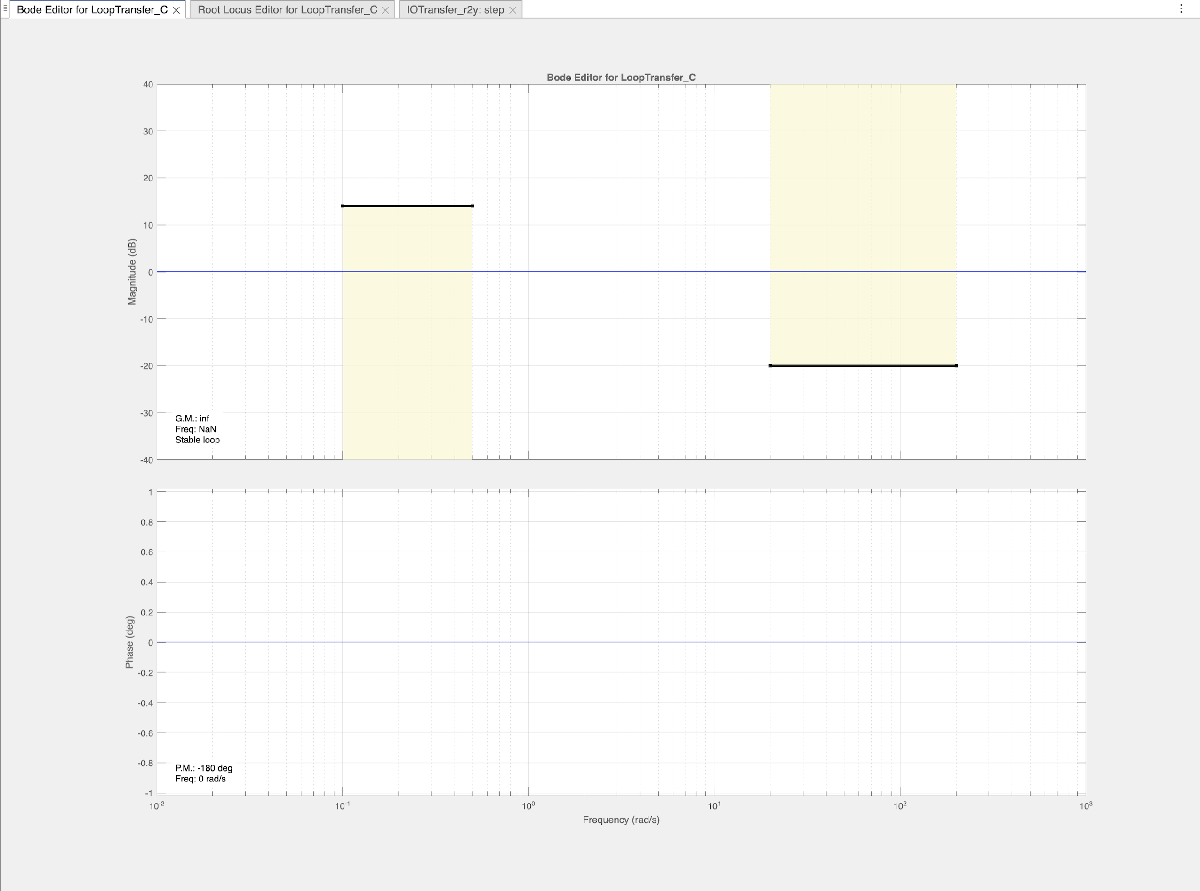		

You will find the session data corresponding to the above Figure in the MAT file named `CSD_reqs_D_N_onlyReqs.MAT .`

The **Bode** **diagram** of the **magnitude** $\left\vert L(j \omega)\right\vert_{\text{dB}}$ **should not cross these yellow regions**, and this graphical constraint provides valuable hints on the shape of the magnitude of the open-loop frequency response.				

As starting design configuration, let us set $\mu_C=1$ and check, using the Control System Designer app, if $\left\vert L(j \omega)\right\vert_{\text{dB}}$ crosses the yellow regions. In case, modify $C(s)$ by adding zeros and/or additional poles.

### A1: Answer to Question Q1

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.		

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 2*(1+10*s)/(1+s)^2; % the process G(s)

As starting configuration, consider the simple controller


$$C_1(s) = \frac{1}{s}$$


muC = 1;
Cs = muC/s;

Ls = Cs * Gs


Ls =
 
     20 s + 2
  ---------------
  s^3 + 2 s^2 + s
 
Continuous-time transfer function.
Model Properties


#### First Approach: Using the Asymptotic Bode Diagrams

Let's draw the asymptotic and the effective Bode diagrams for $L(s)$

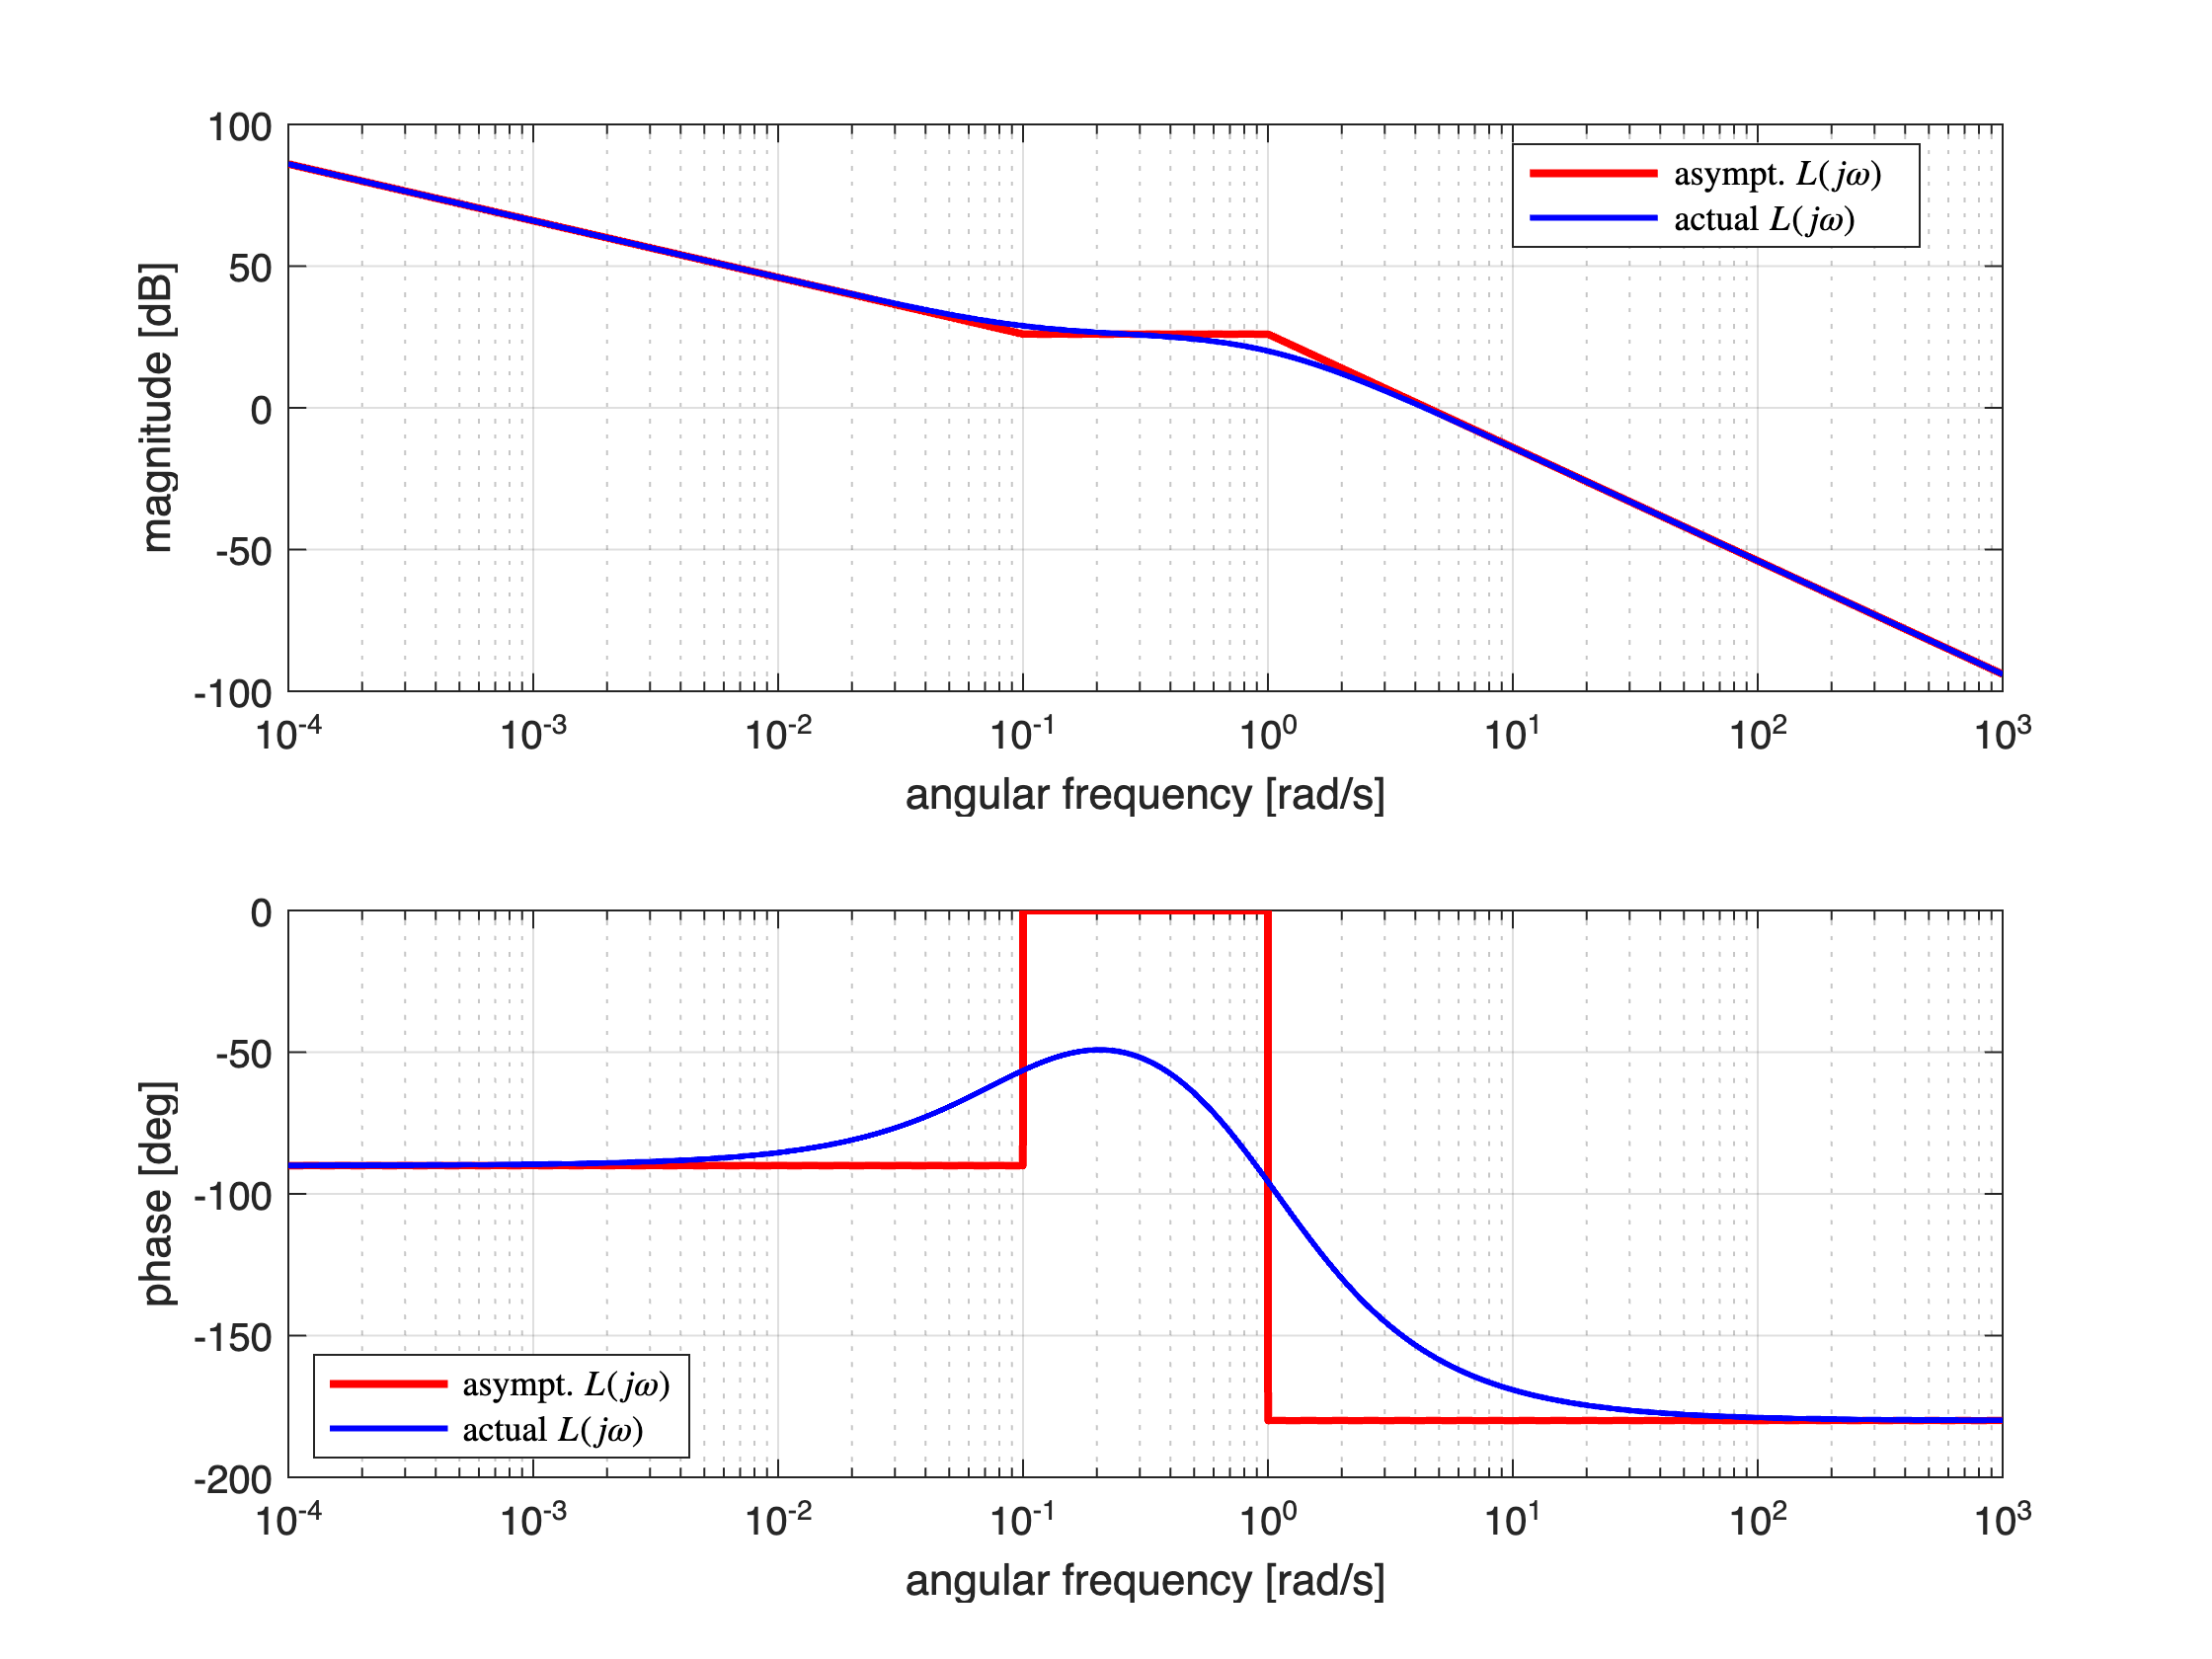

[ha1, ha2] = drawBodediagrams(Ls);
legend(ha1, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
legend(ha2, 'asympt. $L(j \omega)$', 'actual $L(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')

Let us add the constraints on the magnitude $\left\vert L(j \omega)\right\vert_{\text{dB}}$

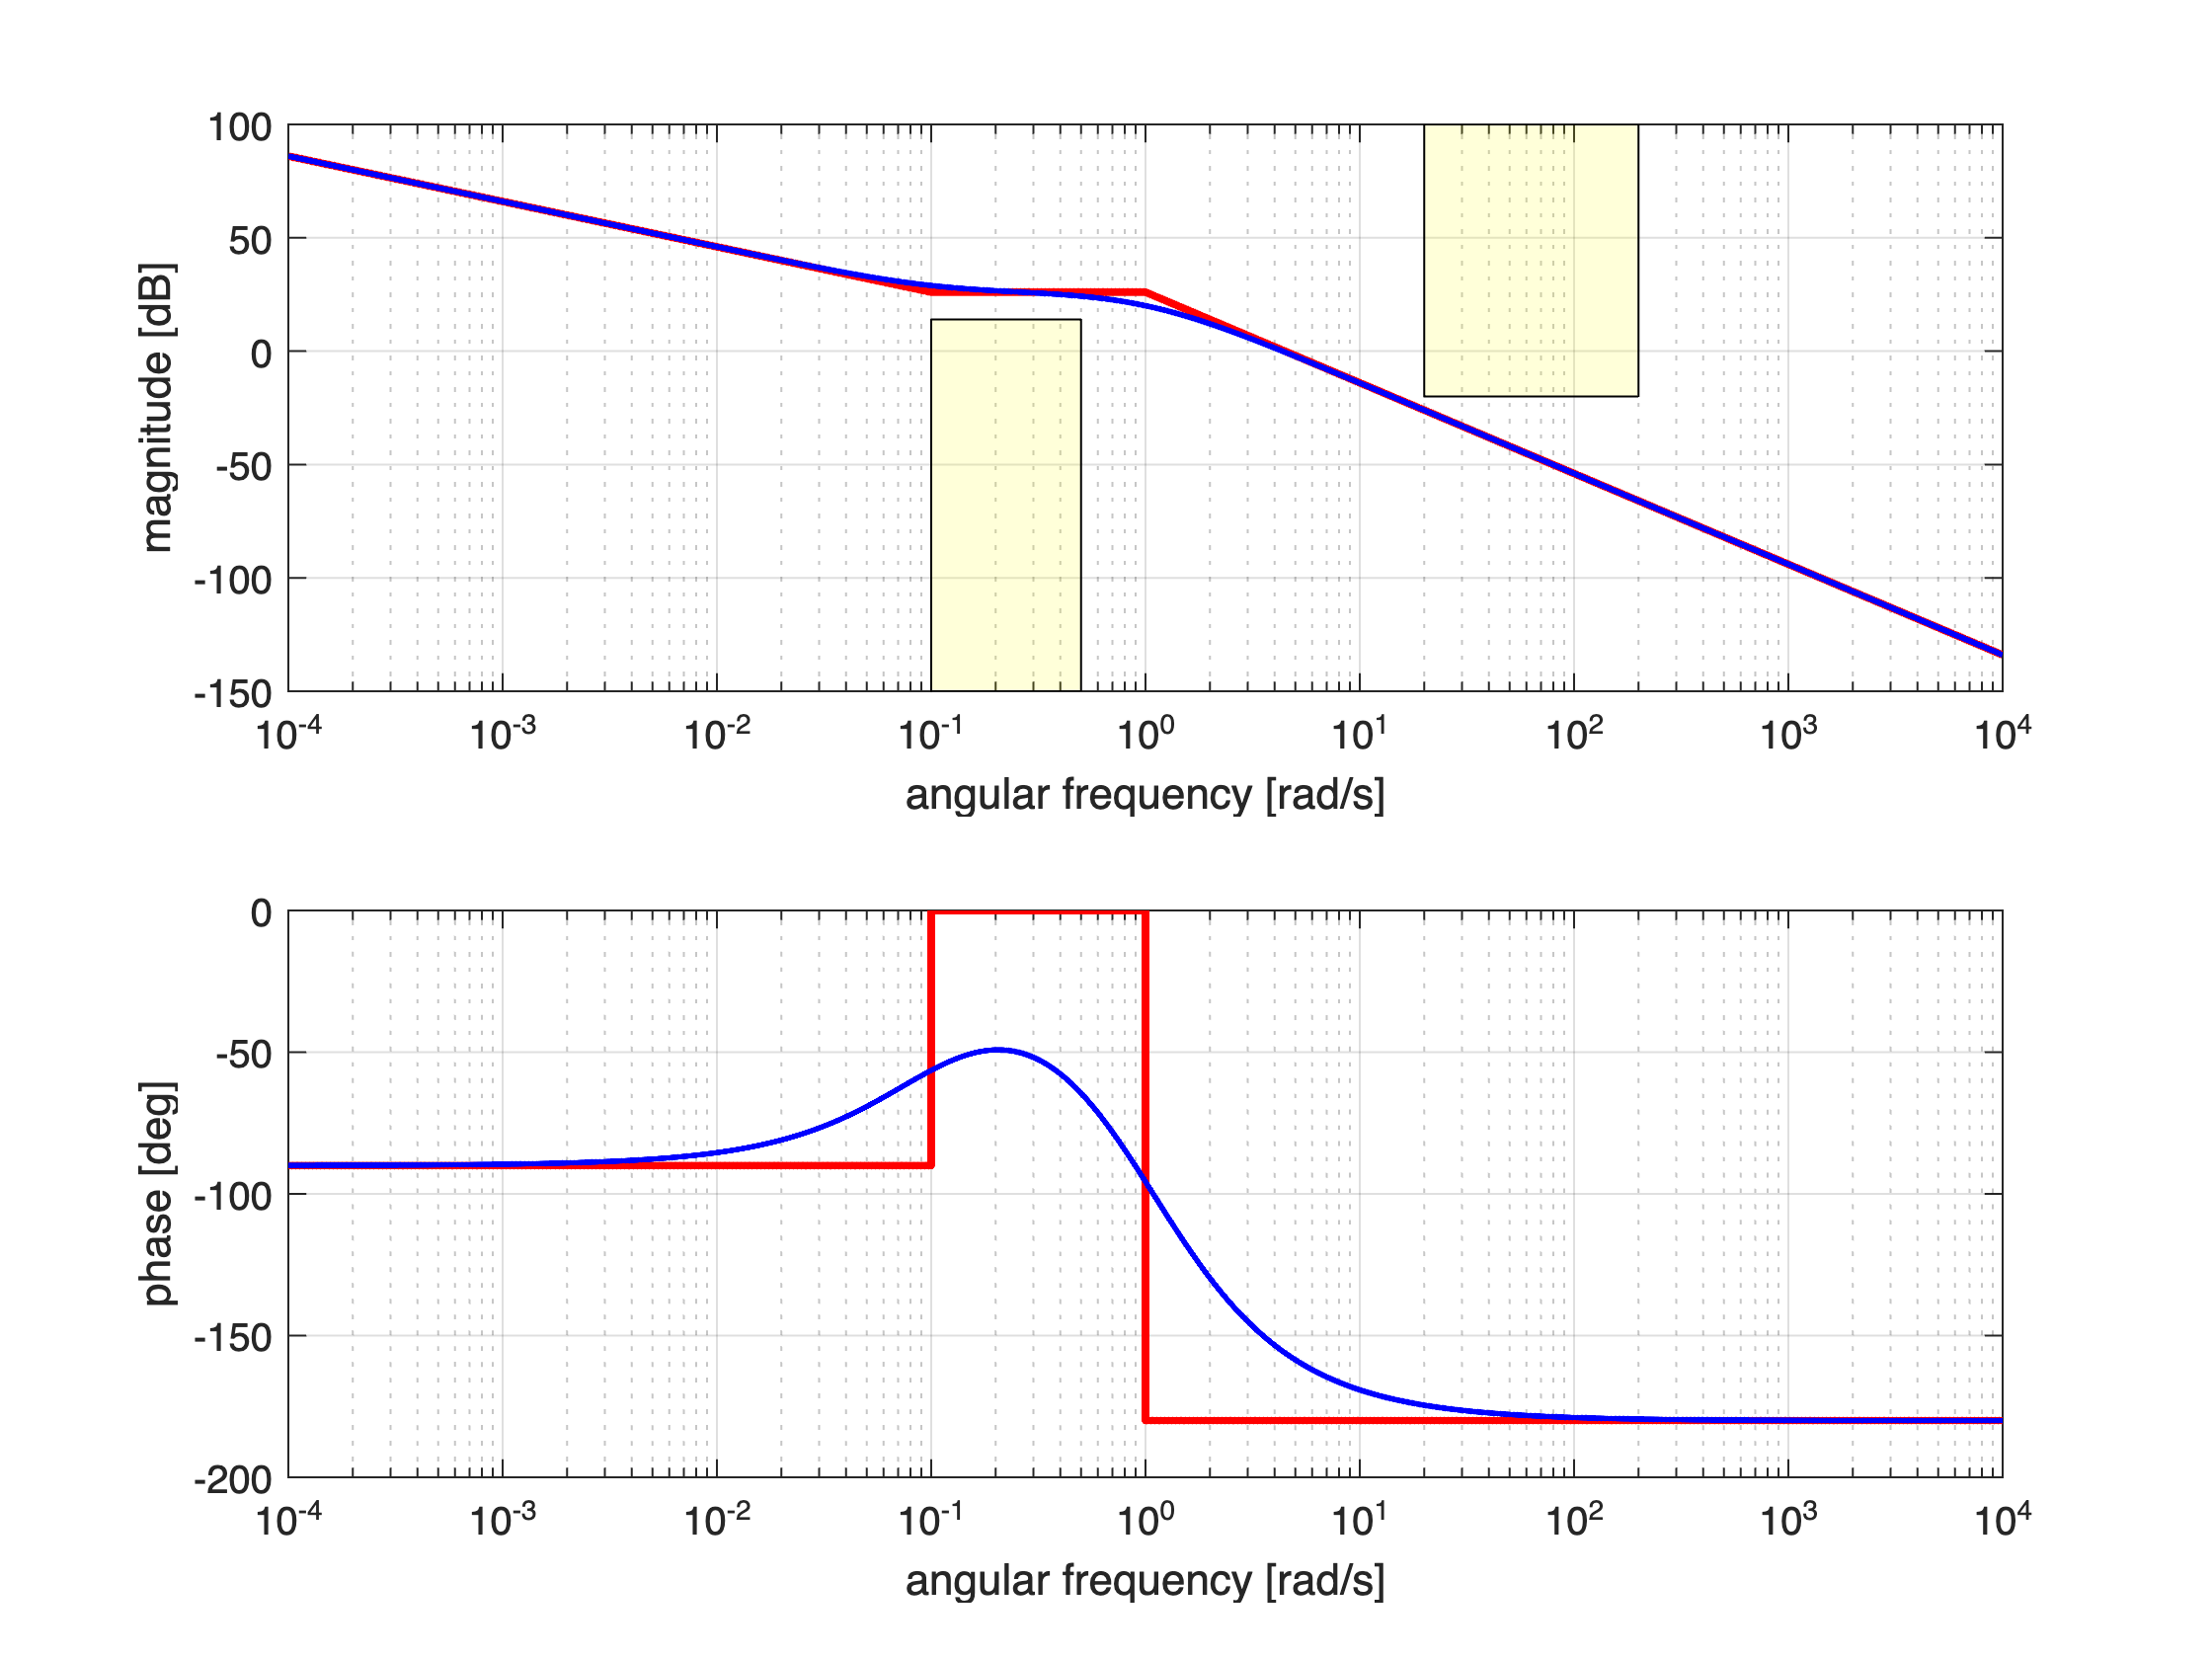

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-4, +4, 1e4); % 10000 values from 1e-4 up to 1e+4
[hax1, hax2] = drawBodediagrams(Ls, omVALS); % Bode diagram

% the (Q1.2) constraint
minOmega1 = 0.1;
maxOmega1 = 0.5;
LMINdB = +14;
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(1); minOmega1 , LMINdB; ...
         maxOmega1 , YLIMs(1); maxOmega1 , LMINdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);
% the (Q1.3) constraint
minOmega2 = 20.0;
maxOmega2 = 200.0;
LMAXdB = -20;
YLIMs = ylim(hax1);
Vert2 = [minOmega2 , LMAXdB; minOmega2 , YLIMs(2) ; ...
         maxOmega2 , YLIMs(2); maxOmega2 , LMAXdB];
Faces2 = [1  2  3  4];
patch(hax1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15);

Notice that by setting $\mu_C = 1$, **all requirements are met** provided that the closed-loop system is asymptotically stable which is true because the phase margin is surely positive.

[~, Pm, ~, OMc] = margin(Ls);
fprintf(['*** Transfer function Ls ***\n\r\n\r' ...
         'Phase margin [deg]: %.4f \n\r',...
         'Crossover Ang. freq. OMc [rad/s]: %.4f \n\r\n\r',...
         '*** Transfer function Ls ***\n\r'], ...
         Pm, OMc);

*** Transfer function Ls ***


Phase margin [deg]: 24.5244 

Crossover Ang. freq. OMc [rad/s]: 4.3595 


*** Transfer function Ls ***



What about the sensitivity transfer function $S(s)$ and the closed-loop transfer function $F(s)$? Let's analyse the frequency response of both the transfer functions:

- Let's analyse the frequency response of the sensitivity function $S(s)$; 

- Note: the requirement on $S(j \omega)$ has been met.

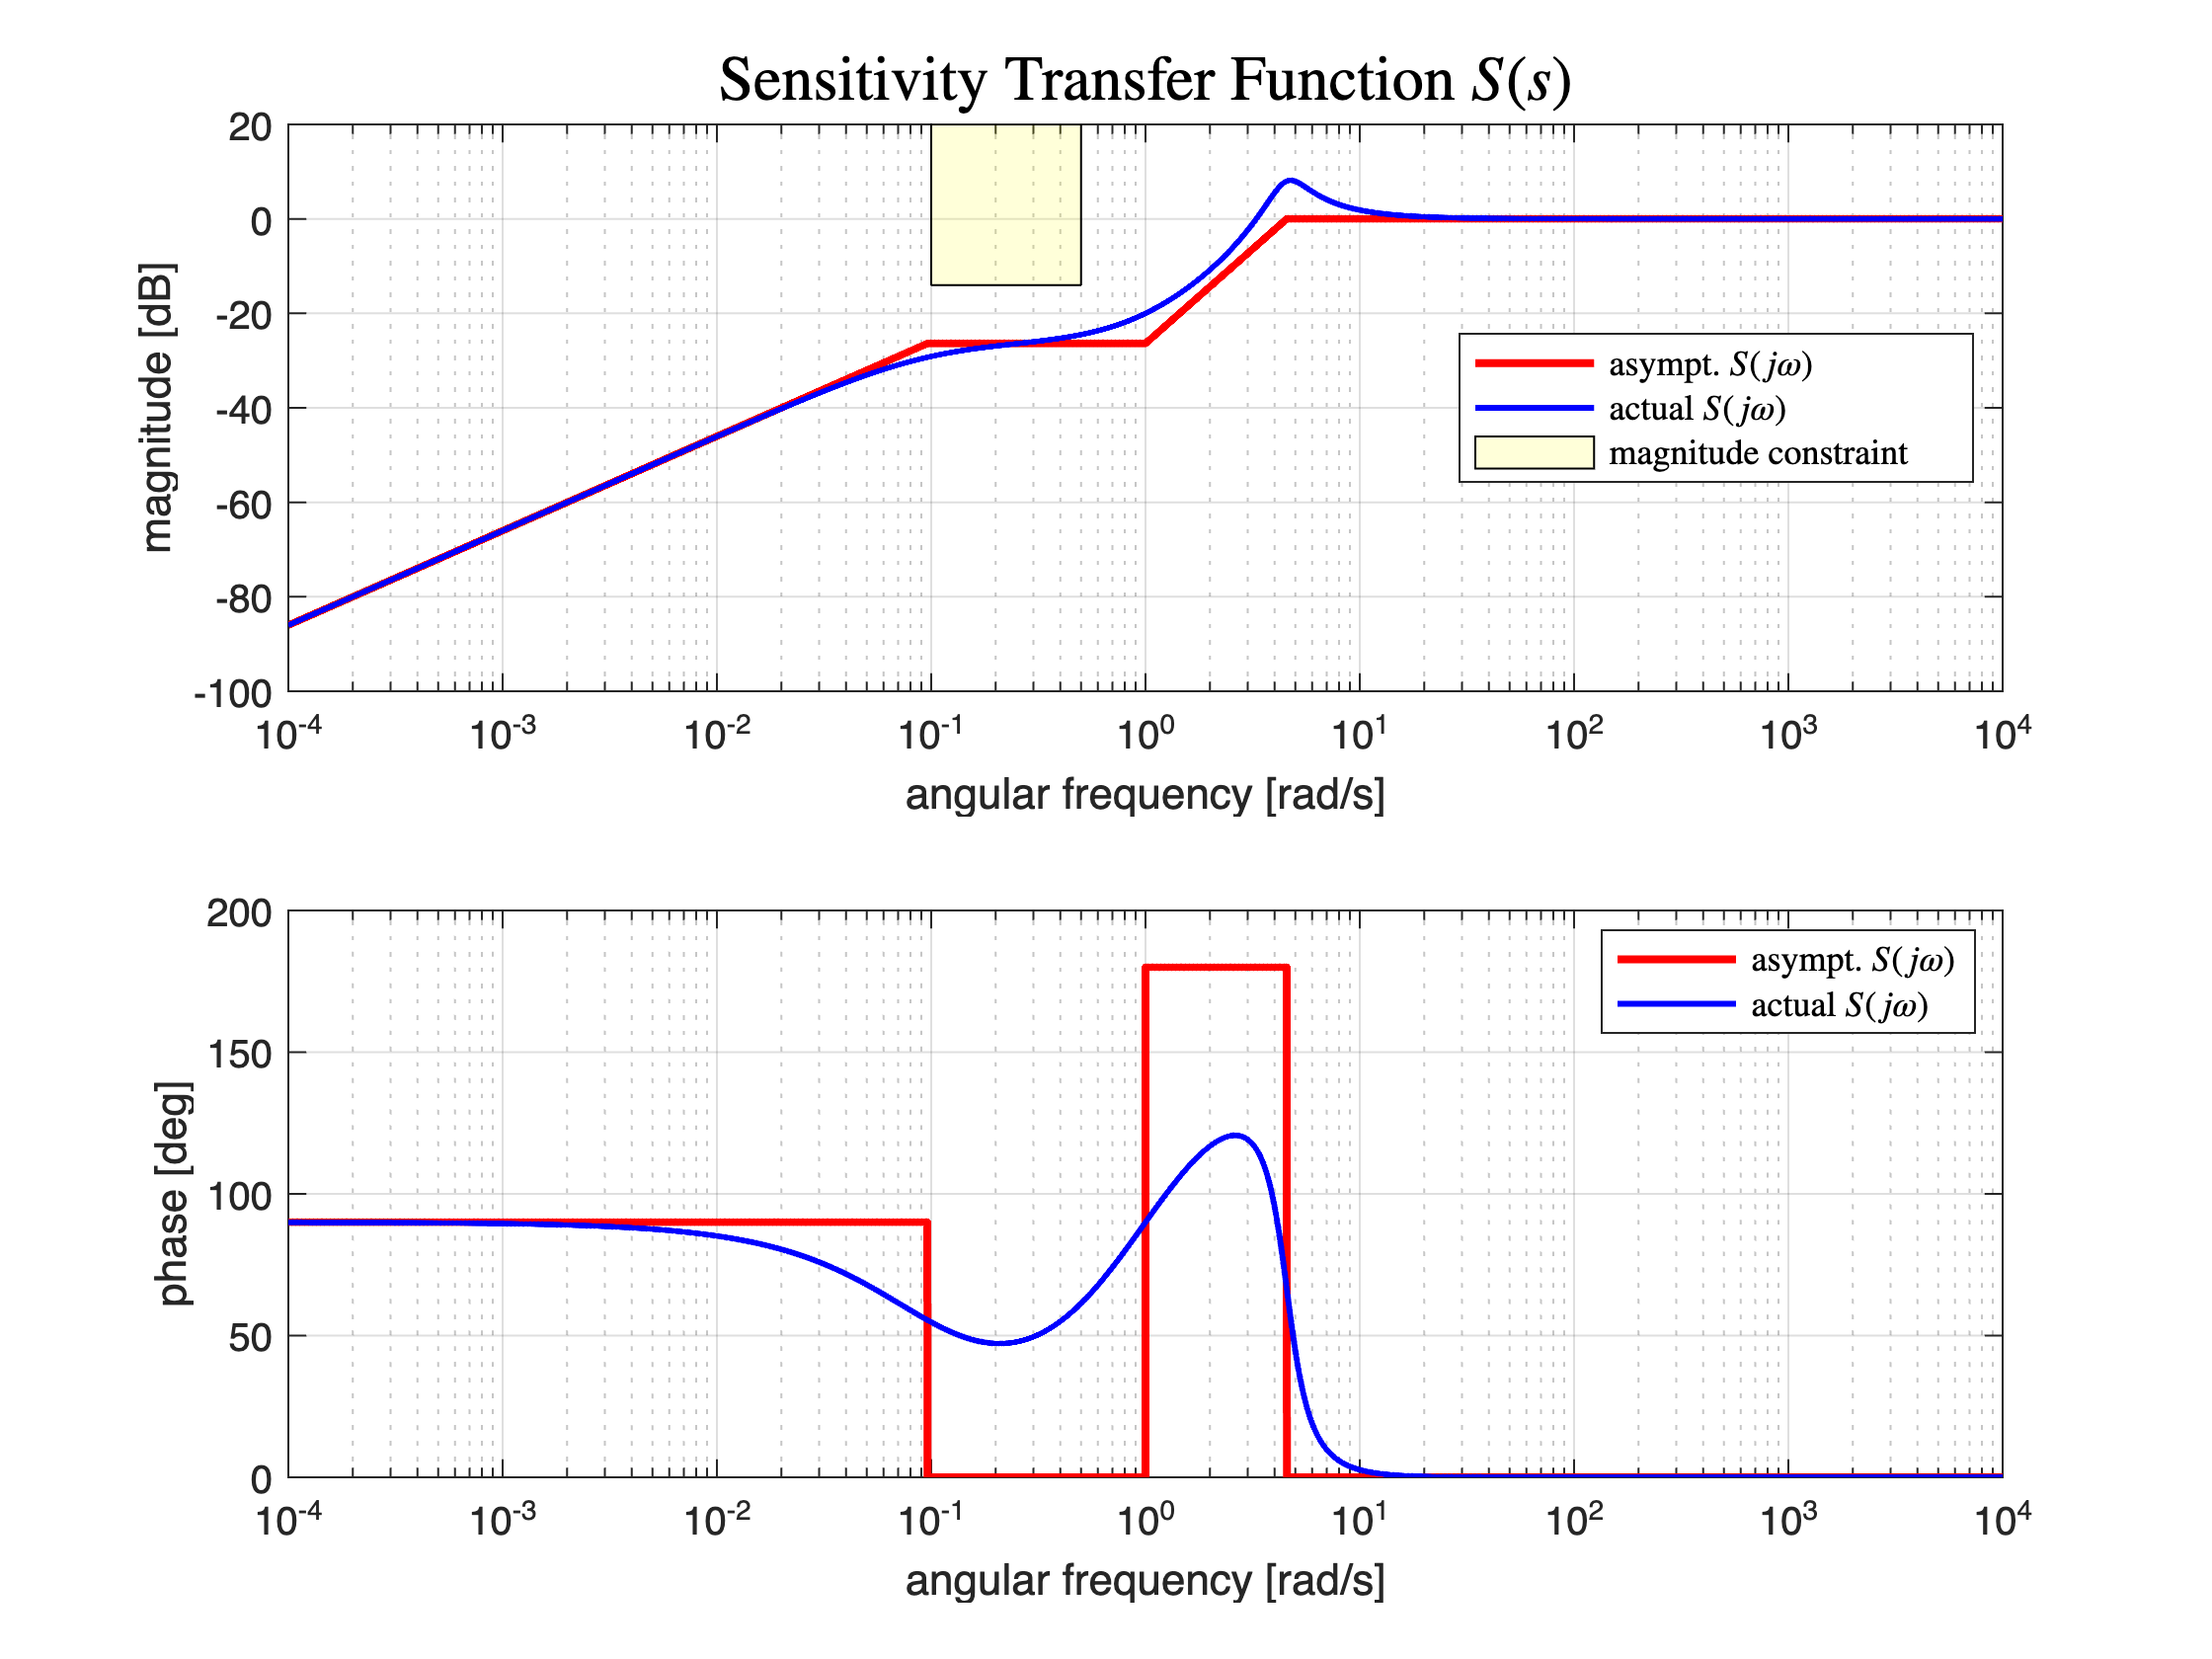

% S(s) = 1/(1+L(s))
Ss = minreal(feedback(1, Ls, -1));
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-4, +4, 1e4); % 10000 values from 1e-4 up to 1e+4
[hax1, hax2] = drawBodediagrams(Ss, omVALS); % Bode diagram

% the (Q1.2) constraint
minOmega1 = 0.1;
maxOmega1 = 0.5;
SMAXdB = -14; % <-- Note: this is the constraint on S(s) !!
YLIMs = ylim(hax1);
Vert1 = [minOmega1 , YLIMs(2); minOmega1 , SMAXdB; ...
         maxOmega1 , YLIMs(2); maxOmega1 , SMAXdB];
Faces1 = [1  2  4  3];
hold on;
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);
legend(hax1, 'asympt. $S(j \omega)$', 'actual $S(j \omega)$', ...
        'magnitude constraint', 'Interpreter', 'latex', 'location', 'best')
legend(hax2, 'asympt. $S(j \omega)$', 'actual $S(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
title(hax1, 'Sensitivity Transfer Function $S(s)$', 'Interpreter','latex', ...
    'FontWeight','bold', 'FontSize',16)

- Now let's analyse the frequency response of the complementary sensitivity function $F(s)$.

- The requirement on $F(j\omega)$ has been met.

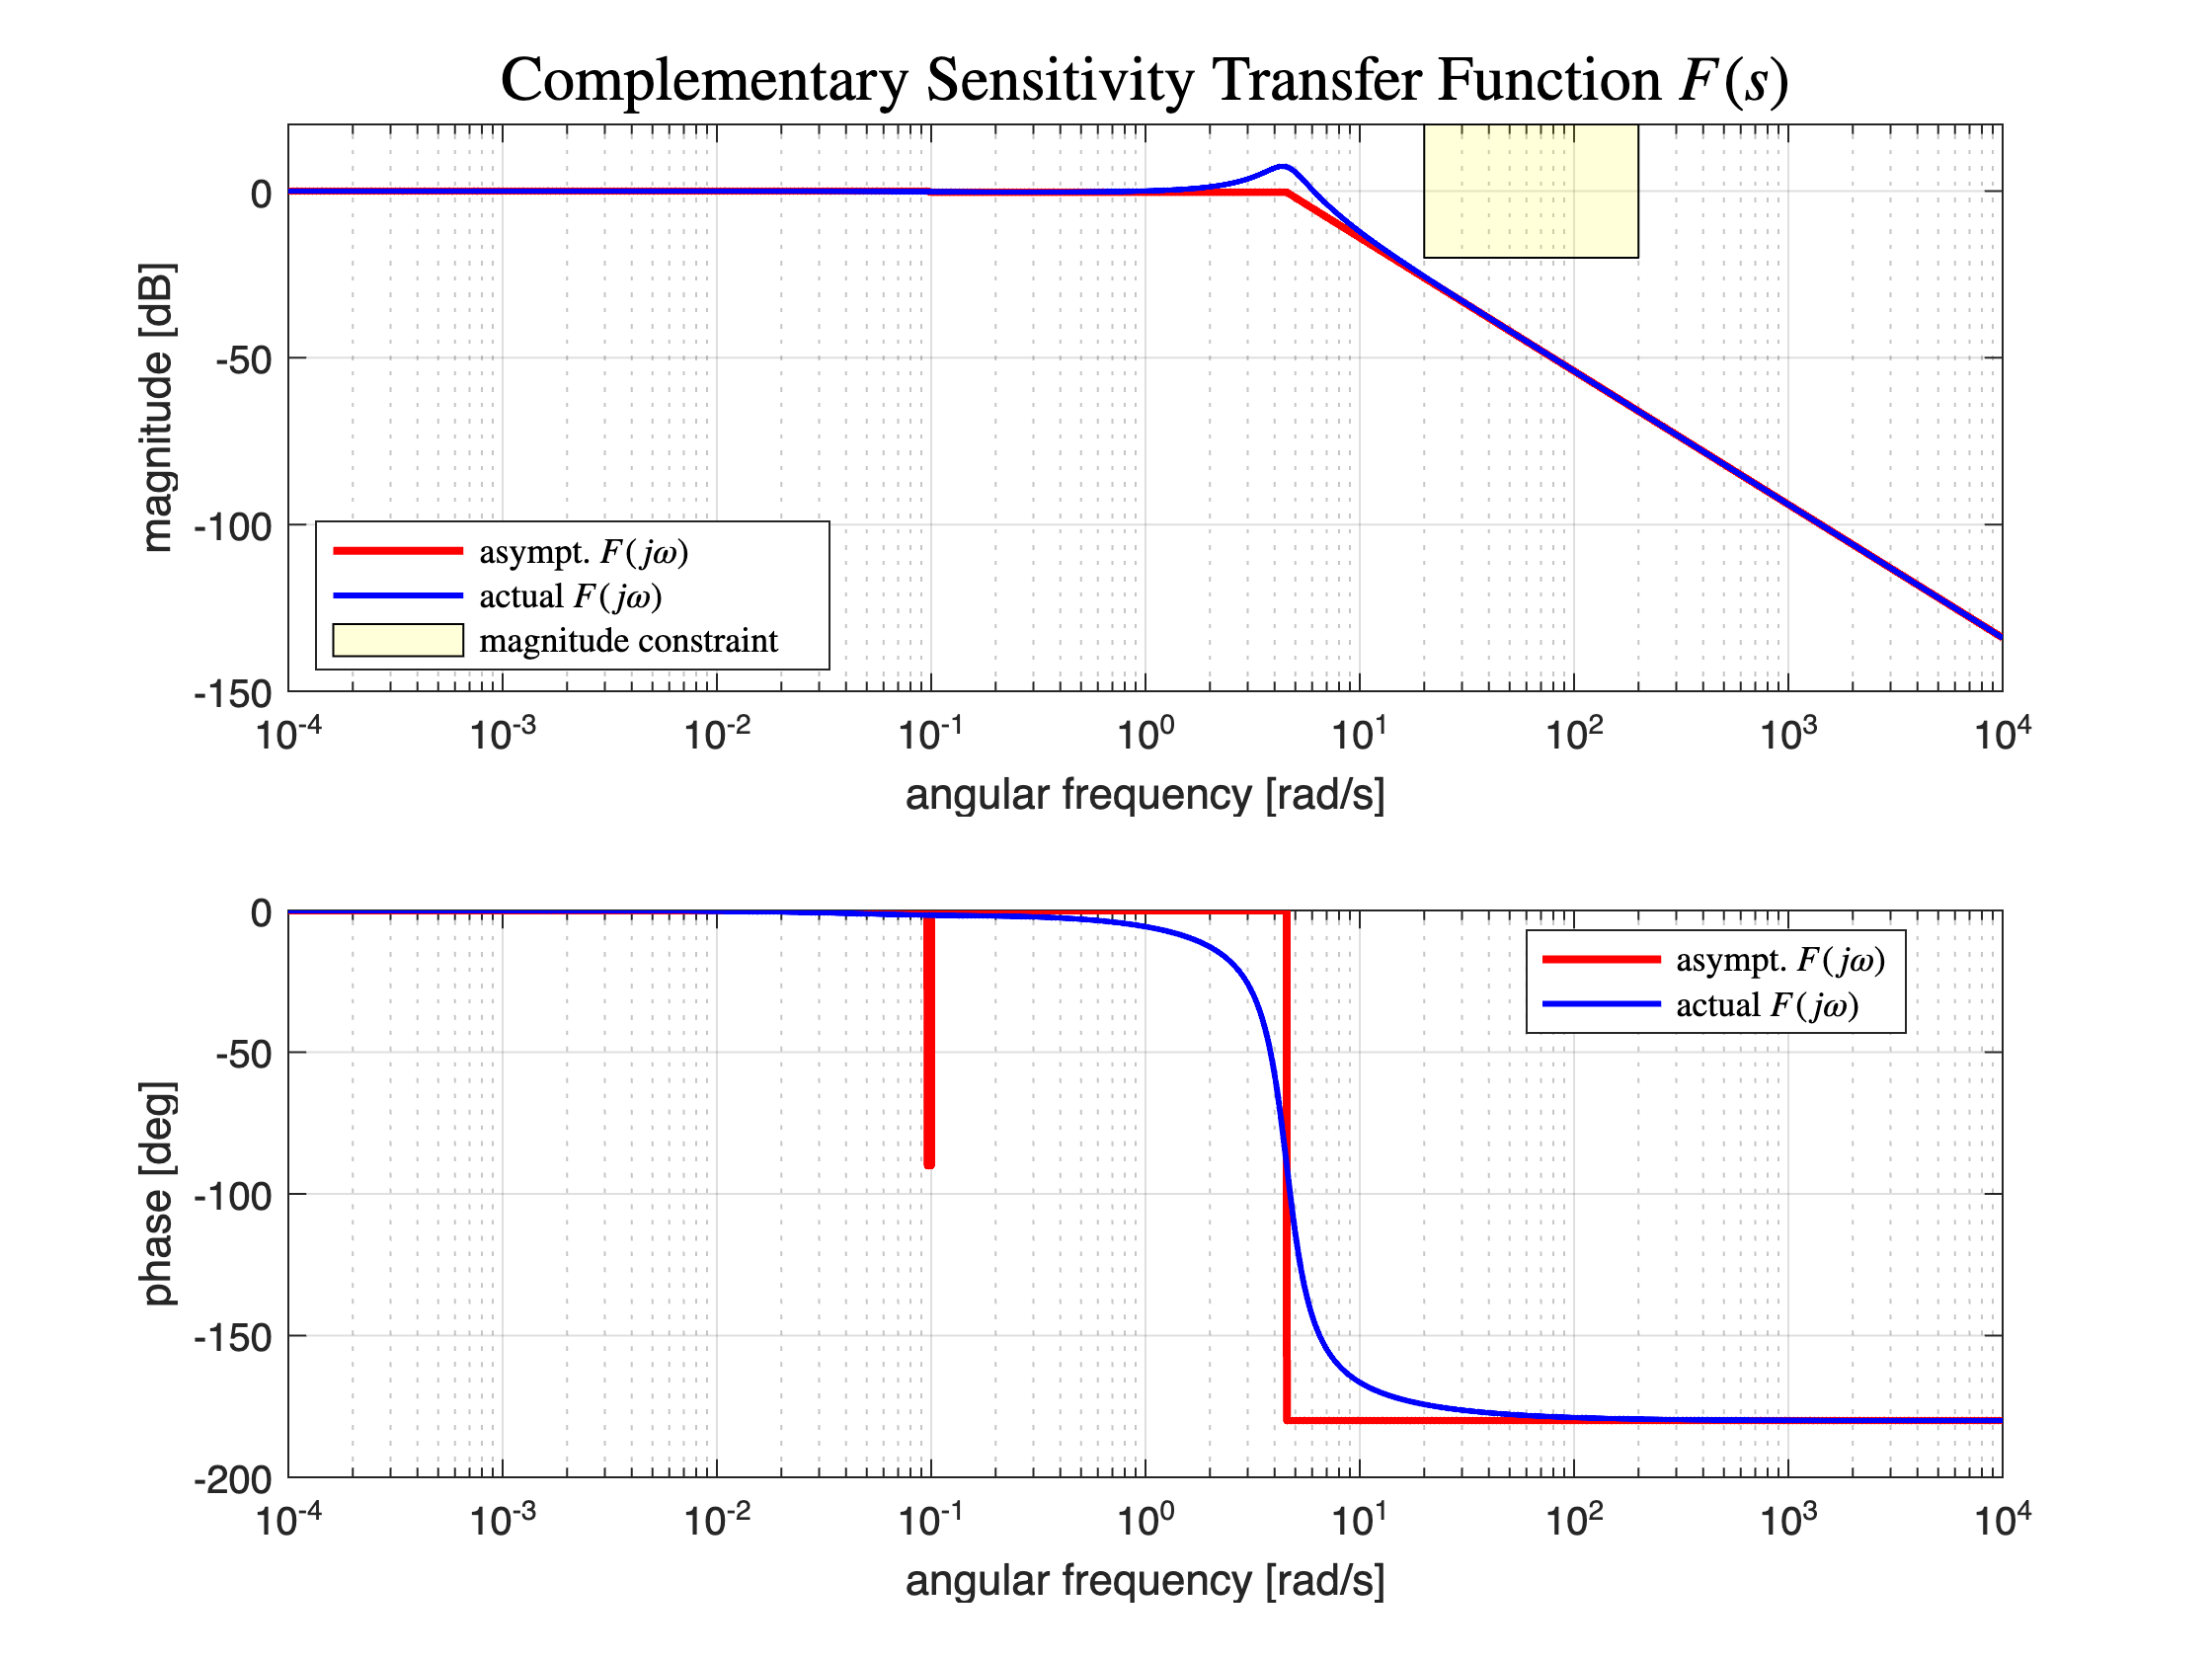

% F(s) = L(s)/(1+L(s))
Fs = minreal(feedback(Ls, 1 ,-1));
hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

omVALS = logspace(-4, +4, 1e4); % 10000 values from 1e-4 up to 1e+4
[hafx1, hafx2] = drawBodediagrams(Fs, omVALS); % Bode diagram

% the (Q1.3) constraint
minOmega1 = 20.0;
maxOmega1 = 200.0;
FMAXdB = -20; % <-- Note: this is the constraint on S(s) !!
YLIMs = ylim(hafx1);
YLIMs(2) = +20.0; % le's enlarge the Y-axis bounds
ylim(hafx1, YLIMs);
Vert1 = [minOmega1 , YLIMs(2); minOmega1 , FMAXdB; ...
         maxOmega1 , YLIMs(2); maxOmega1 , FMAXdB];
Faces1 = [1  2  4  3];
hold on;
patch(hafx1, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15);
legend(hafx1, 'asympt. $F(j \omega)$', 'actual $F(j \omega)$', ...
        'magnitude constraint', 'Interpreter', 'latex', 'location', 'best')
legend(hafx2, 'asympt. $F(j \omega)$', 'actual $F(j \omega)$', ...
        'Interpreter', 'latex', 'location', 'best')
title(hafx1, 'Complementary Sensitivity Transfer Function $F(s)$', 'Interpreter','latex', ...
    'FontWeight','bold', 'FontSize',16)

#### Preferred Approach: Using the Control System Design App

Let's open the **Control System Designer App** and import both the process transfer function $G(s)$ and the initial guess for the controller $C(s)$ 

controlSystemDesigner(Gs, Cs);

Define the constraints on the magnitude of the frequency response $L(j\omega)$

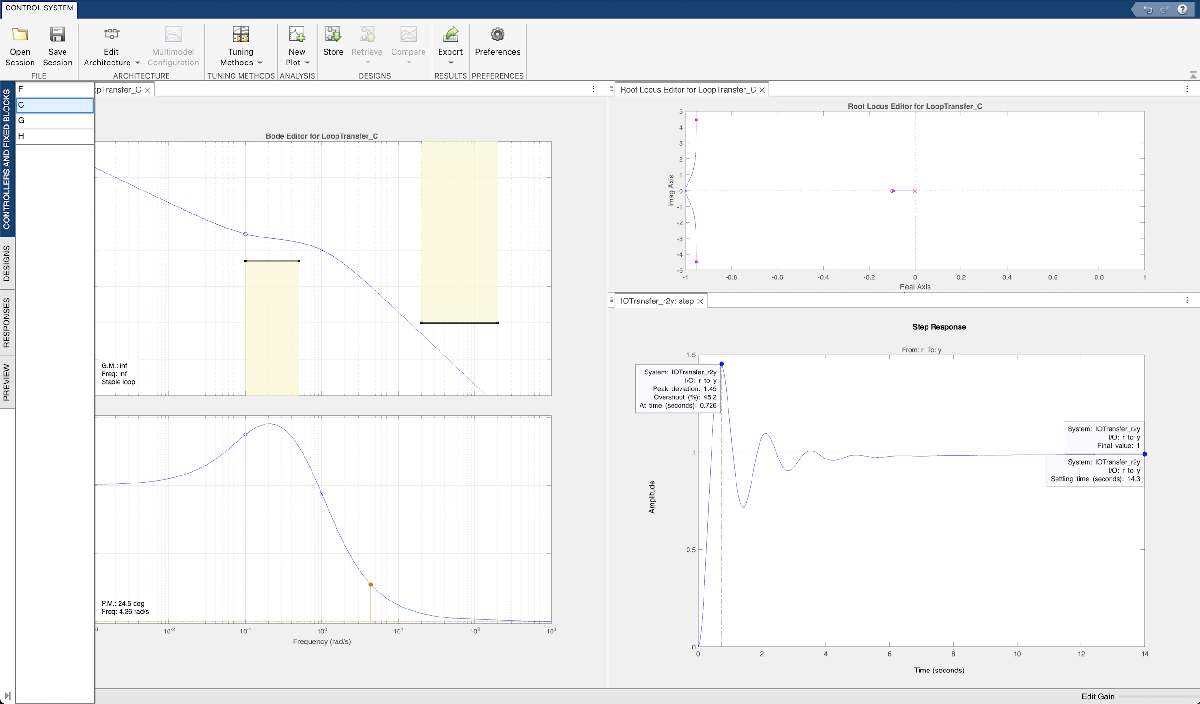

You will find the session data corresponding to the above Figure in the MAT file named `CSD_reqs_D_N_muC_1.MAT .`

Notice that by setting $\mu_C = 1$, **all requirements are met** provided that the closed-loop system is asymptotically stable which is true because the phase margin is positive.

**Fine Tuning **

As it can easily spotted, we can **improve** the control system **performance** by simply **decreasing** **the** **gain** $\mu_C$, still keeping the magnitude diagram away from the yellow areas.

By selecting, for example, the gain value$\mu_C = 0.36$, we obtain

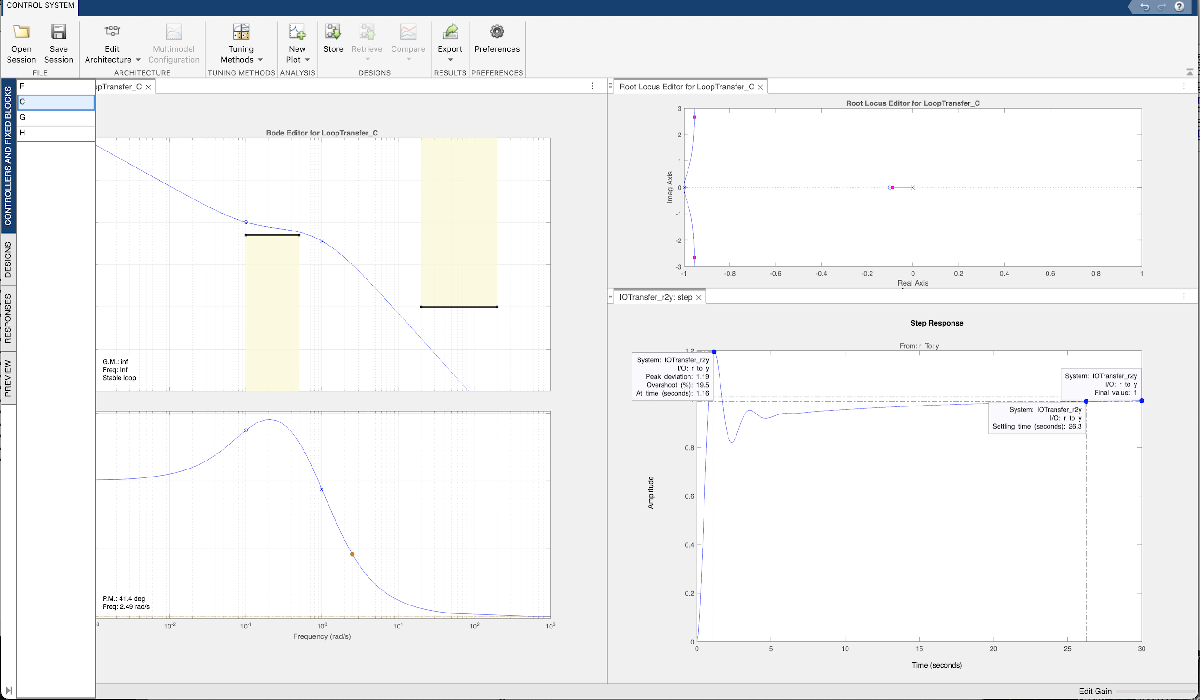

You will find the session data corresponding to the above Figure in the MAT file named `CSD_reqs_D_N_muC_036.MAT .`

What about the sensitivity transfer function $S(s)$ and the closed-loop transfer function $F(s)$? 

Let's analyse the frequency response of both the transfer functions, using the `controlSystemDesigner` app: let's **add two more plots**, the frequency response of the sensitivity function $S(j \omega)$ and the frequency response of the closed-loop transfer function $F(j \omega)$.

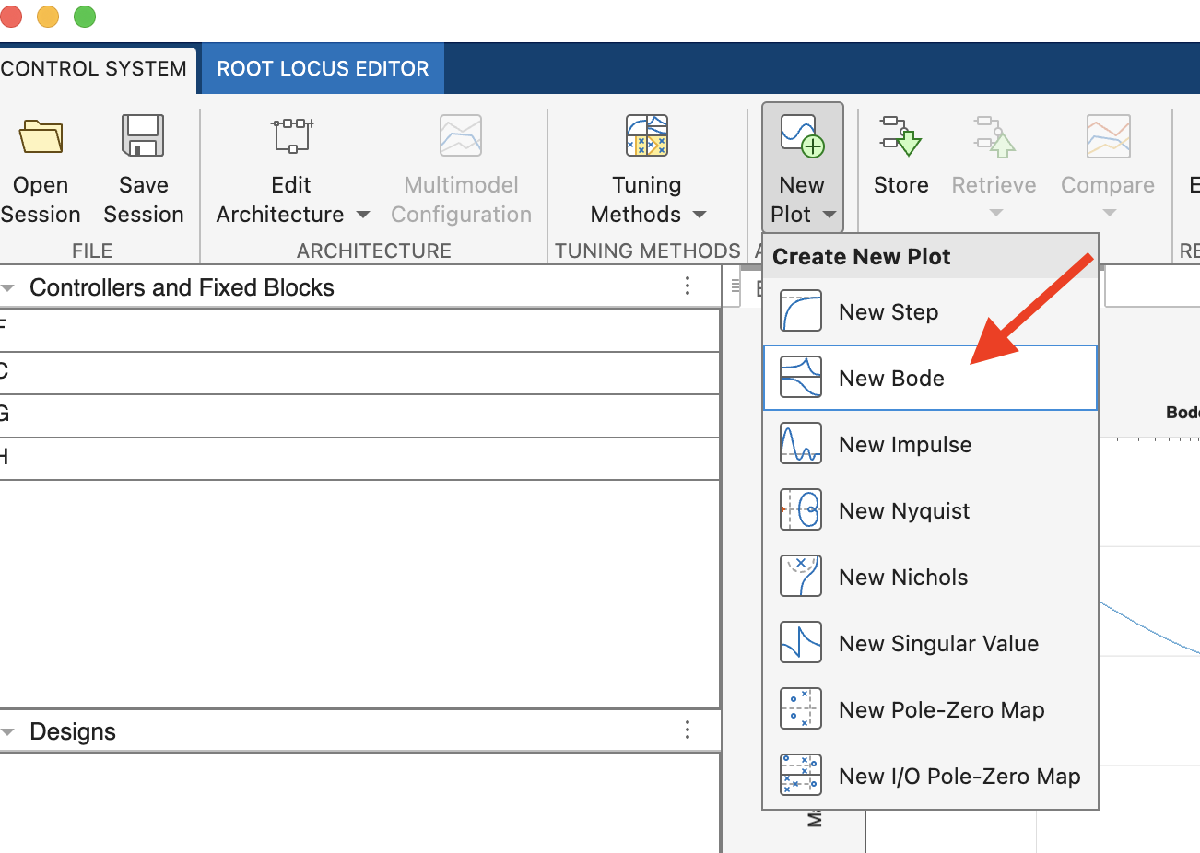

Let's add the plots of the frequency responses $S(j\omega)$ and $F(j\omega)$:

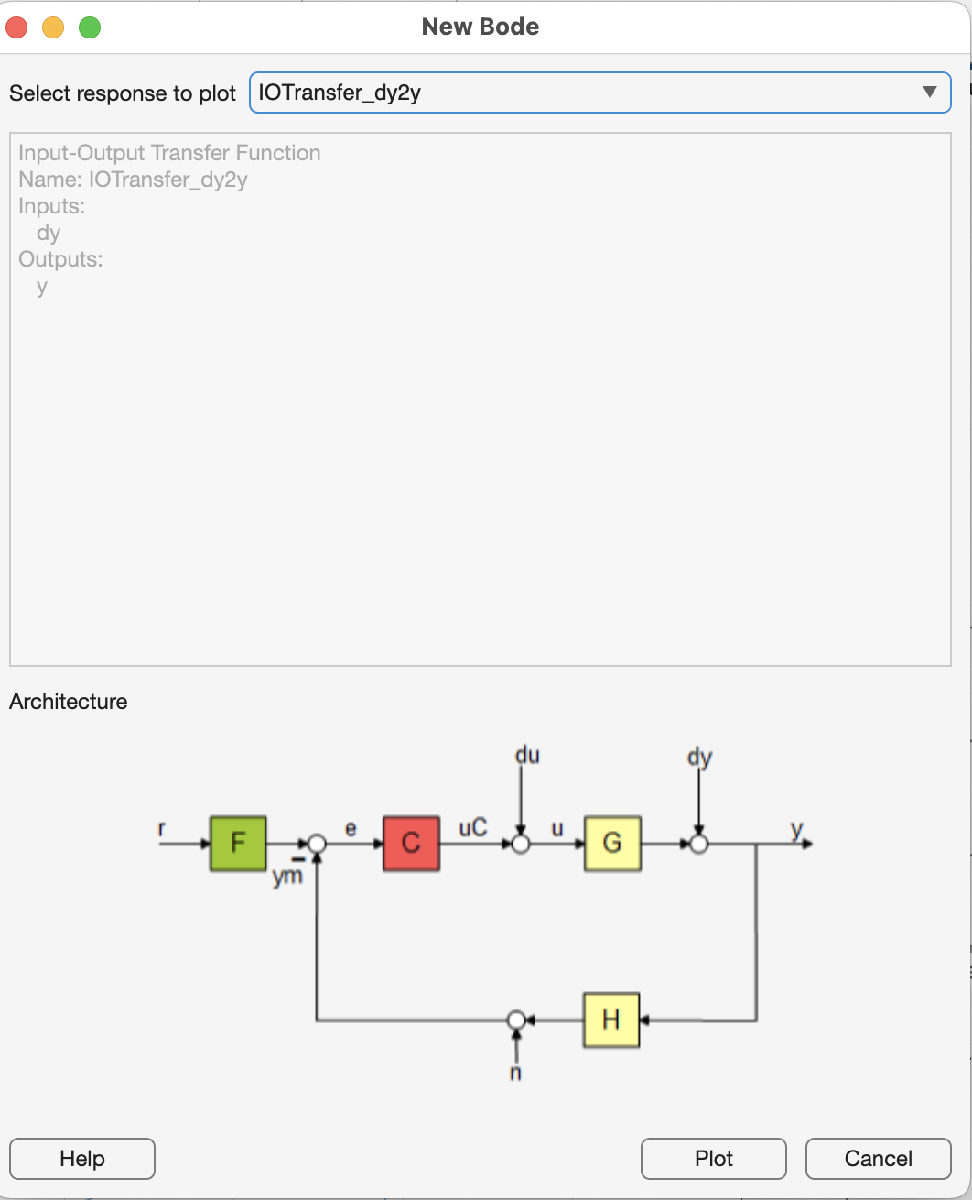    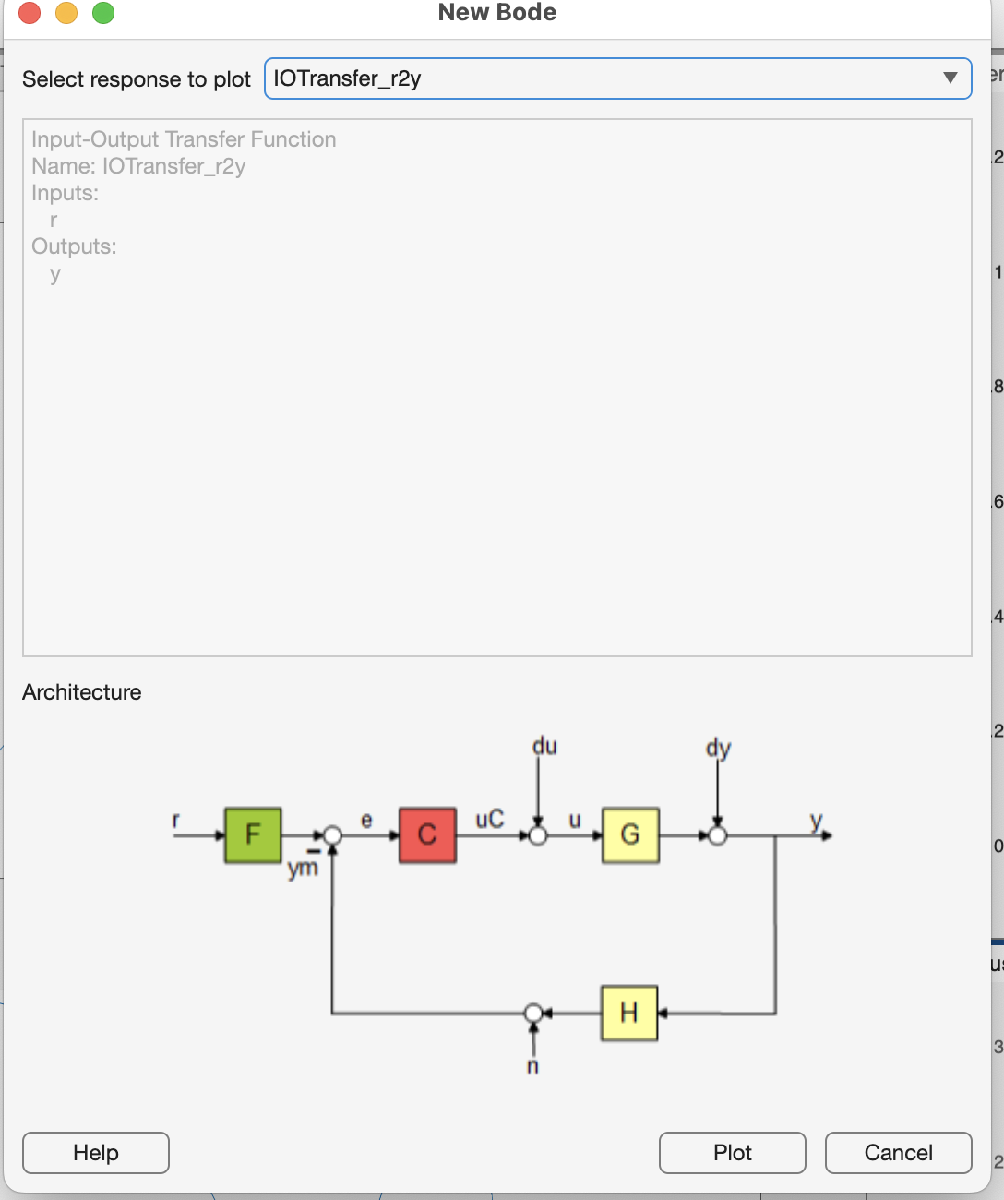

Verify that requirements Q1.2 and Q1.3 have been met. 

Let's start with the initial controller, with $\mu_c=1$:

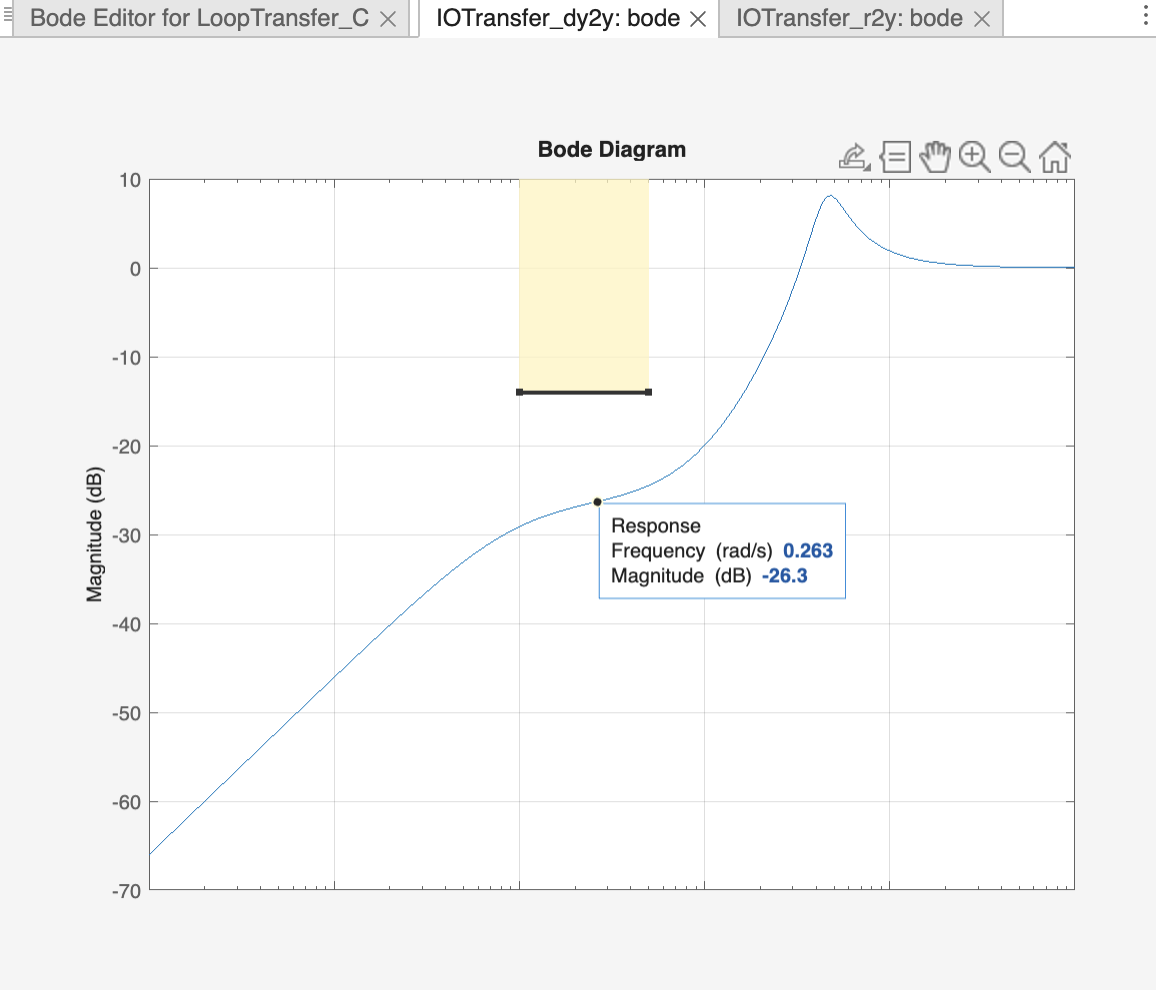    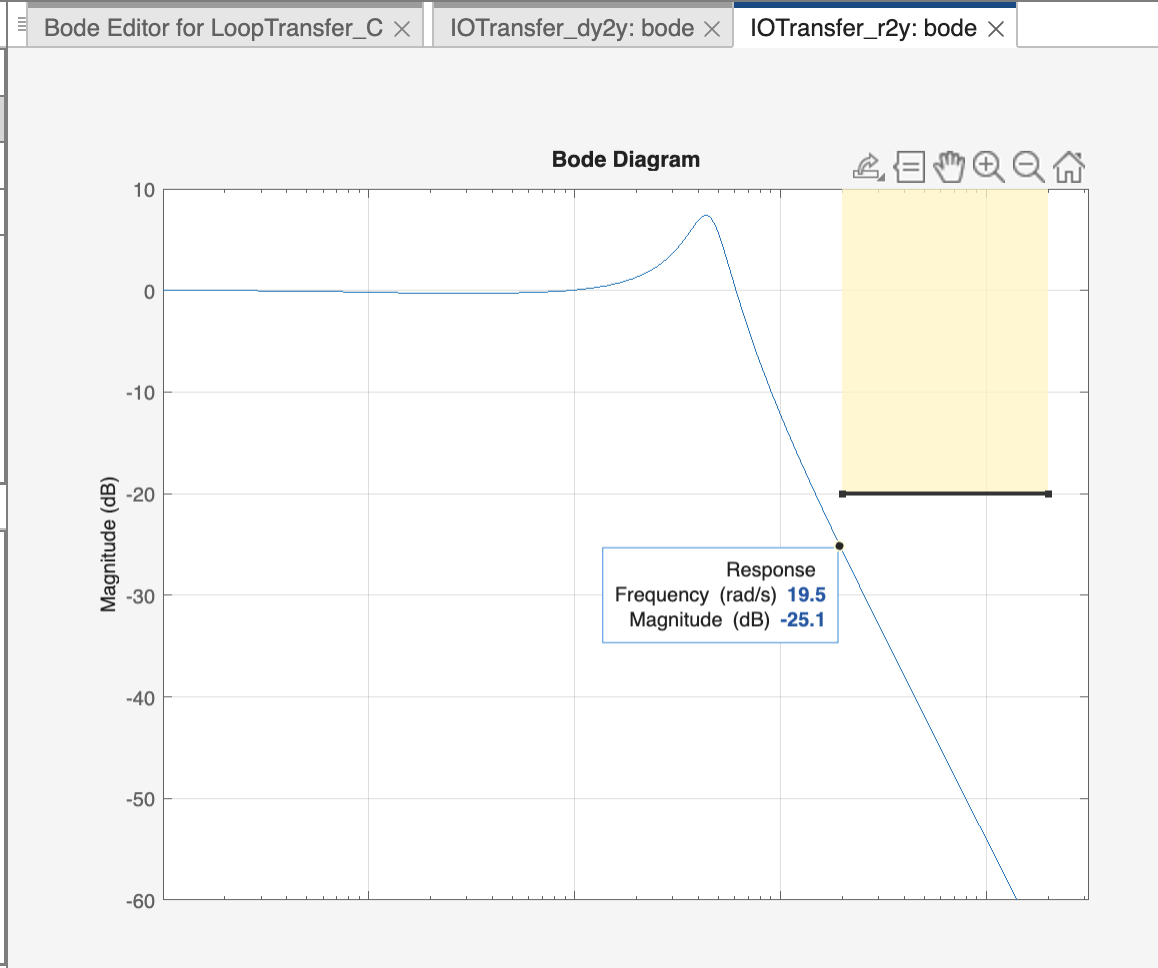

As expected, the requirements are met.

Finally, let's analyse the latter proposal, with $\mu_c=0.36$:

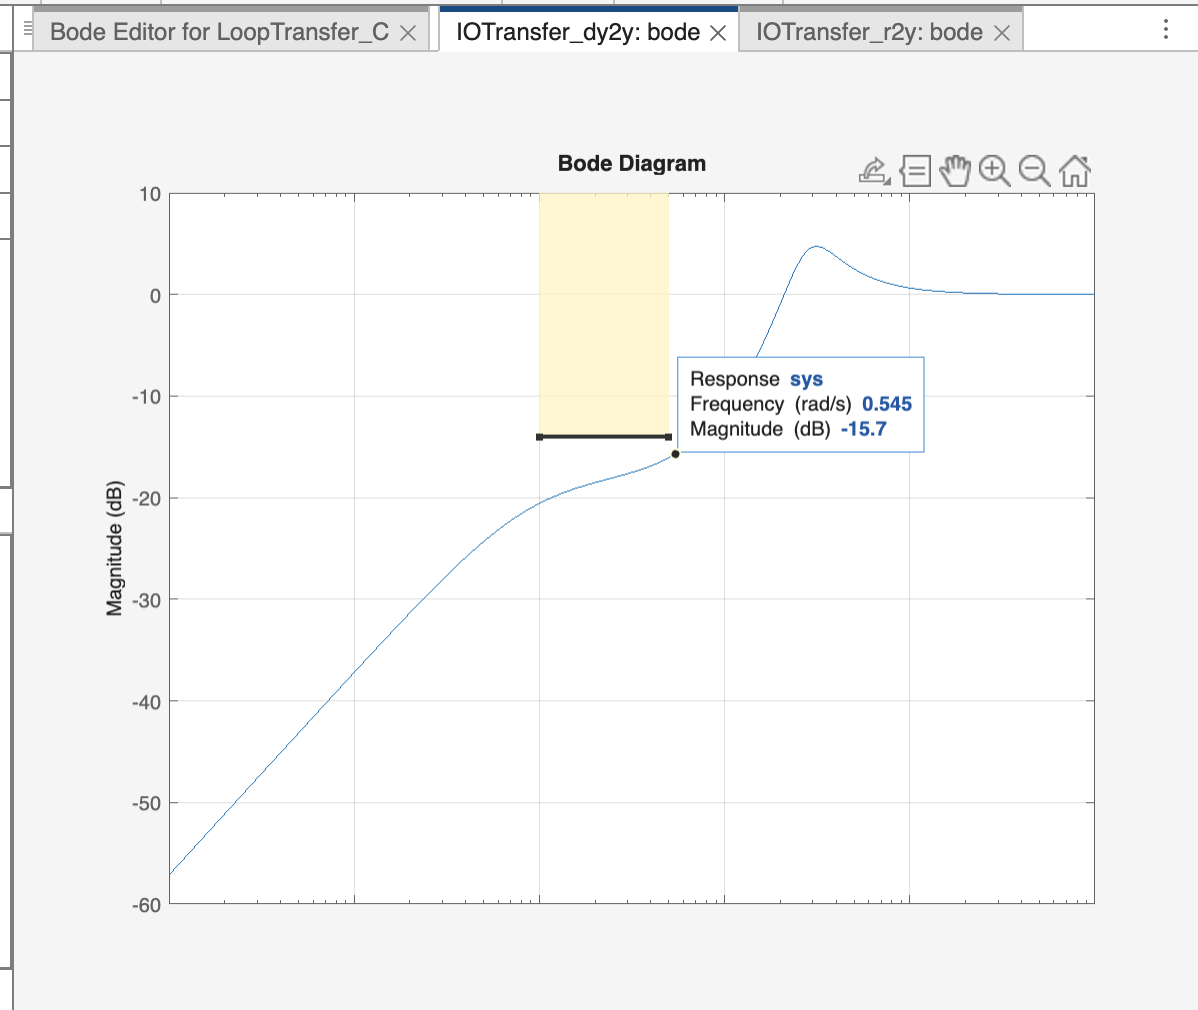    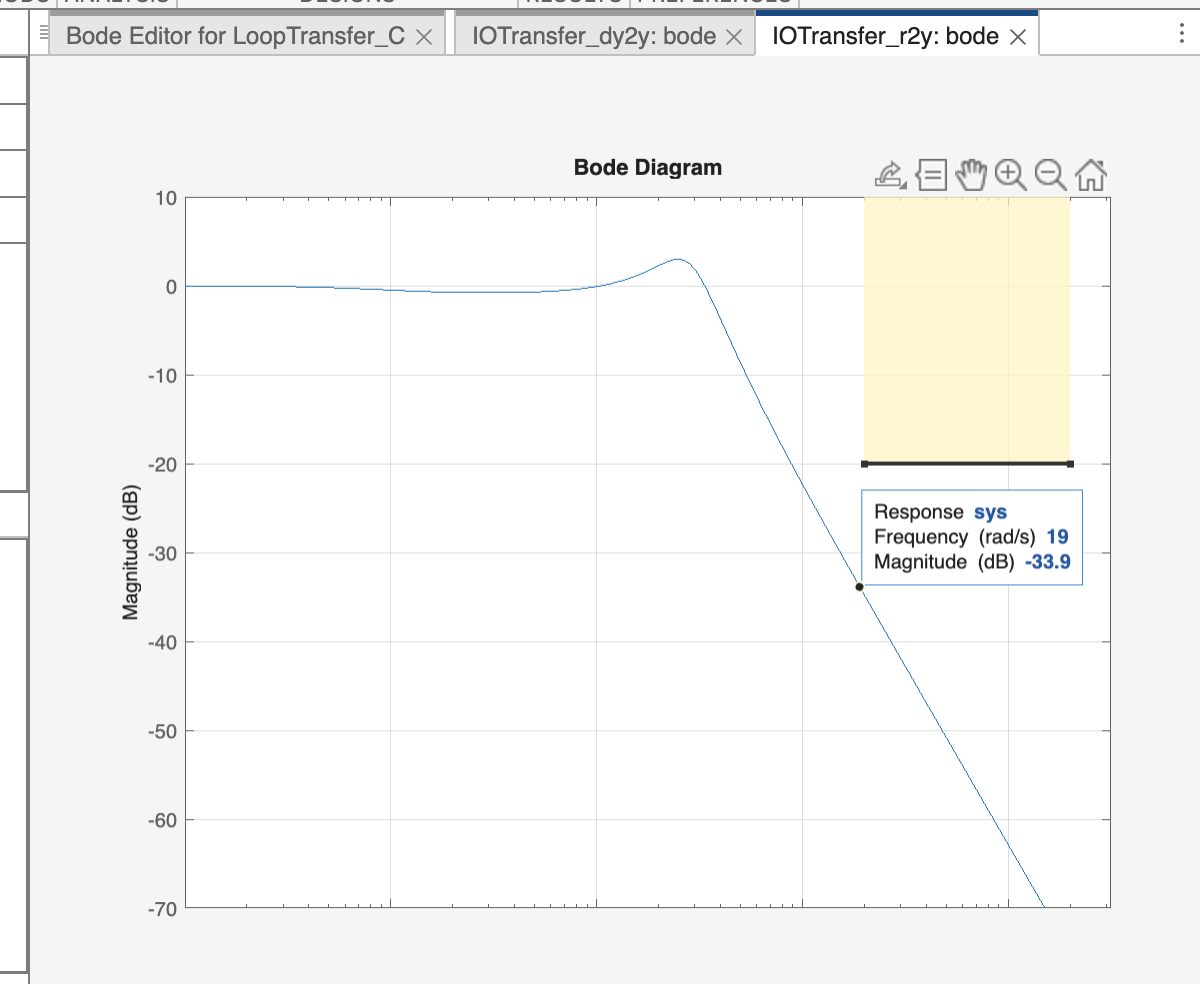

As expected, the requirements are met.

### Concluding Remarks

- **Both** the proposed **solutions** are **feasible**, and in both scenarios, **all the requirements are met**. 

- The second proposal is preferable, due to the larger phase margin.